clear
clc

load('hall.mat');
[h,w] = size(hall_gray,[1 2]);
blockamountW = ceil(w/8);
blockamountH = ceil(h/8);

方法2：用信息位逐一替换每个8x8DCT系数块中(2:4,2:4)的部分，再进行熵编码

info = int32(randi([0 1],3*blockamountH,3*blockamountW));
[ACstream,DCstream,h,w] = DCTconceal2(hall_gray,info);
infoRtv = DCTretrieve2(ACstream,DCstream,h,w);

获取信息隐藏图像

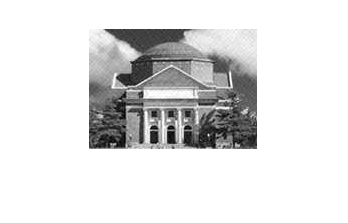

ImageConceal = JpegDecoder(DCstream,ACstream,h,w);
imshow(ImageConceal);

计算PSNR

MSE = sum((ImageConceal-hall_gray).^2,'all')/h/w;
PSNR = 10 * log10(255^2/MSE);

计算压缩率

compressrate = 8*h*w/(length(ACstream)+length(DCstream));

评估信息还原的准确率

ErrorMtx = bitxor(info,infoRtv); % 按位异或得错误
fidelity = 1-sum(ErrorMtx,"all")/h/w; % 还原率

PSNR = 33.2751, 33.2779, 33.3021, 33.2821, 33.3764

compressrate = 5.8102, 5.8096, 5.7969, 5.7875, 5.8276

fidelity = 1, 1, 1, 1, 1